# F1 Trajectory Optimization using Kinematic Bicycle Model

Linearized model with track boundary constraints

clear; clc;

## 1. Load Track Data

% CSV columns: x, y, width_right, width_left
track_data  = readmatrix('Nuerburgring.csv');
x_center    = track_data(:,1);
y_center    = track_data(:,2);
width_right = track_data(:,3);
width_left  = track_data(:,4);

N_track = length(x_center);

## 2. Vehicle Parameters

l         = 2.5;           % Wheelbase [m]
v_max     = 80;            % Max velocity [m/s]
v_min     = 5;             % Min velocity [m/s]
a_max     = 10;            % Max accel [m/s^2]
a_min     = -15;           % Max braking [m/s^2]
delta_max = tan(deg2rad(20));   % Steering bounds [rad]
delta_min = tan(-deg2rad(20));
v=20;

N  = N_track;   % one step per track sample


## 3. Compute Track Headings and Boundaries

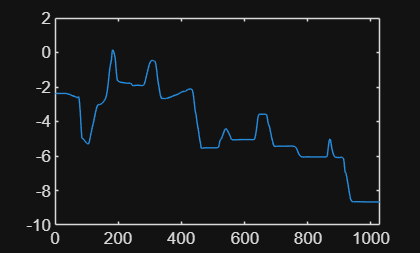


theta_track = zeros(N,1);
for k = 1:N-1
    theta_track(k) = atan2(y_center(k+1) - y_center(k), ...
                           x_center(k+1) - x_center(k));
    if k >= 2
        if ((theta_track(k) - theta_track(k-1)) >= pi)
        theta_track(k) = theta_track(k) - 2*pi;
        end
        if ((theta_track(k) - theta_track(k-1)) <= -pi)
            theta_track(k) = theta_track(k) + 2*pi;
        end
    end
end

theta_track(N) = theta_track(N-1);
plot(theta_track);


% Left and right boundaries (absolute coordinates)
x_left  = x_center - width_left  .* sin(theta_track);
y_left  = y_center + width_left  .* cos(theta_track);
x_right = x_center + width_right .* sin(theta_track);
y_right = y_center - width_right .* cos(theta_track);


## 4. Reference Trajectory (Centerline)

x_r     = x_center;
y_r     = y_center;
theta_r = theta_track;
v_r     = v;
delta_r = zeros(N,1);

## 5. Decision Variables

x     = sdpvar(N,1);
y     = sdpvar(N,1);
theta = sdpvar(N,1);     
delta = sdpvar(N-1,1);     % steering


## 6. Constraints

constraints = [];

% % Initial conditions: start on centerline, reference speed
% constraints = [constraints, x(1) == x_center(1)];
% constraints = [constraints, y(1) == y_center(1)];
% constraints = [constraints, theta(1) == theta_track(1)];
% constraints = [constraints, v(1) == v_r(1)];

dx = sdpvar(N,1);
dy = sdpvar(N,1);
dtheta = sdpvar(N,1);
z = sdpvar(N,1);

constraints = [constraints, ...
    % dx(1) == 0, dy(1) == 0, 
    % dtheta(1) == 0, ...
    x == x_left + z.*(x_right-x_left) , ...
    y == y_left + z.*(y_right-y_left) ,...
    dtheta == theta - theta_r];

% Dynamics (linearized around reference)
for k = 1:N-1
    
    d = sqrt((x_center(k+1)-x_center(k))^2+(y_center(k+1)-y_center(k))^2);
    Ts = d/v;
    % % x dynamics
    % x_dot = v*cos(theta_r(k)) ...
    %       - v_r*sin(theta_r(k))*dtheta(k);
    % constraints = [constraints, x(k+1) == x(k) + Ts*x_dot];
    % 
    % % y dynamics
    % y_dot = v*sin(theta_r(k)) ...
    %       + v*cos(theta_r(k))*dtheta(k);
    % constraints = [constraints, y(k+1) == y(k) + Ts*y_dot];

    constraints = [constraints, ((x(k+1) - x(k)) * (-sin(theta_r(k))) + (y(k+1) - y(k)) * cos(theta_r(k))) == d * dtheta(k)];

    % theta dynamics
    theta_dot = v/l * delta(k);             
    constraints = [constraints, theta(k+1) == theta(k) + Ts*theta_dot];
    
end

% Track Constraints
constraints = [constraints, z >= 0, z <= 1];

% Bounds
constraints = [constraints, (delta_min <= delta), (delta <= delta_max)];

## 7. Objective (quadratic, Gurobi-kompatibel)

### 7.1 TRUE F1 PATH LENGTH MINIMIZATION

dx_seg = sdpvar(N-1,1); dy_seg = sdpvar(N-1,1);
dx_seg_p = sdpvar(N-1,1); dx_seg_m = sdpvar(N-1,1);
dy_seg_p = sdpvar(N-1,1); dy_seg_m = sdpvar(N-1,1);
delta_p = sdpvar(N-1,1); delta_m = sdpvar(N-1,1);

for k = 1:N-1
    constraints = [constraints, ...
        dx_seg(k) == x(k+1) - x(k), ...
        dy_seg(k) == y(k+1) - y(k), ...
        dx_seg(k) == dx_seg_p(k) - dx_seg_m(k), dx_seg_p(k)>=0, dx_seg_m(k)>=0, ...
        dy_seg(k) == dy_seg_p(k) - dy_seg_m(k), dy_seg_p(k)>=0, dy_seg_m(k)>=0];
end

constraints = [constraints, delta == delta_p - delta_m, delta_p>=0, delta_m>=0];


### 7.2 Lateral Deviation

s = sdpvar(N,1);      % signed deviation

for k = 1:N
    n_x = -sin(theta_r(k));
    n_y =  cos(theta_r(k));
    s(k) = n_x*dx(k) + n_y*dy(k);

    % constraints = [constraints, ...
    %     (-width_left(k) - eps_s(k) <= s(k)) & (s(k) <= width_right(k) + eps_s(k))];
    % constraints = [constraints, ...
    %     s(k) == s_p(k) - s_m(k), ...
    %     s_p(k) >= 0, s_m(k) >= 0]
end

### 7.3 Steering

dDelta = sdpvar(N-2,1);
dDelta_p = sdpvar(N-2,1);
dDelta_m = sdpvar(N-2,1);

for k = 1:N-2
    constraints = [constraints, ...
        dDelta(k) == delta(k+1) - delta(k), ...
        dDelta(k) == dDelta_p(k) - dDelta_m(k), ...
        dDelta_p(k) >= 0, dDelta_m(k) >= 0];
end

### 7.4 Curvature

kappa = sdpvar(N-1,1);    % curvature per segment
w_kappa = 1e5;            % strong penalty, tune

for k = 1:N-1
    d = sqrt((x_center(k+1)-x_center(k))^2 + (y_center(k+1)-y_center(k))^2);

    % define curvature as heading change over arc length
    constraints = [constraints, ...
        kappa(k) == (theta(k+1) - theta(k)) / d];
end

### 7.5 Objective Function

objective = 0;

w_pl     = 20;
w_lat    = 0.5;
w_steer  = 2;
w_smooth = 100;


% path length
objective = objective + w_pl * sum(0.5*(dx_seg_p + dx_seg_m) + (dy_seg_p + dy_seg_m));

% % lateral deviation
objective = objective + w_lat * (s.'*s);

% steering
objective = objective + w_steer * sum(delta_p + delta_m);

% smoothness
objective = objective + w_smooth * sum(dDelta_p + dDelta_m);

% curvature penalty 
objective = objective + w_kappa * (kappa.' * kappa);



## 8. Solve

options = sdpsettings('solver','gurobi','verbose',1);
options.gurobi.Method = 1;
sol = optimize(constraints, objective, options);

Set parameter WLSAccessID
Set parameter WLSSecret
Set parameter LicenseID to value 2748332
Set parameter Method to value 1
Set parameter LPWarmStart to value 1
Set parameter NodefileDir to value ""
Set parameter NLPHeur to value 1
Set parameter TuneTimeLimit to value 1e+100
Academic license 2748332 - for non-commercial use only - registered to pa___@studenti.unipr.it
Gurobi Optimizer version 13.0.0 build v13.0.0rc1 (win64 - Windows 11+.0 (26200.2))

CPU model: Intel(R) Core(TM) i7-8565U CPU @ 1.80GHz, instruction set [SSE2|AVX|AVX2]
Thread count: 4 physical cores, 8 logical processors, using up to 8 threads

Non-default parameters:
Method  1
LPWarmStart  1
NLPHeur  1
TuneTimeLimit  1e+100

Academic license 2748332 - for non-commercial use only - registered to pa___@studenti.unipr.it
Optimize a model with 25701 rows, 20564 columns and 51400 nonzeros (Min)
Model fingerprint: 0xa6ccff1f
Model has 8222 linear objective coefficients
Model has 4115 quadratic objective terms
Coefficient stati

## 9. Diagnosis

disp('YALMIP solve status:');

YALMIP solve status:


disp(sol.problem);

     0



disp(sol.info);

Successfully solved (GUROBI)


yalmiperror(sol.problem);

if sol.problem ~= 0
    warning('Problem not solved to optimality. Check constraints.');
    return;
end

## 11. Extract Solution

x_opt     = value(x);
y_opt     = value(y);
theta_opt = value(theta);
delta_opt = value(delta);

lap_time = N * Ts;
fprintf('Lap time (approx, fixed Ts): %.2f s\n', lap_time);

Lap time (approx, fixed Ts): 257.34 s


## 12. Plots

raceline_file = 'C:\Users\patri\Documents\Uni\Parma\PATP\Path-Trajectory-Planning-2025\patrick_files\Nuerburgring_raceline.csv';

% Load Raceline
fprintf('Loading TUM raceline...\n');

Loading TUM raceline...


opts2 = detectImportOptions(raceline_file);
opts2.Delimiter = ',';
opts2.VariableNamingRule = 'preserve';
data_race = readtable(raceline_file, opts2);
x_race_raw = data_race.x_m;
y_race_raw = data_race.y_m;



### Plot Raceline

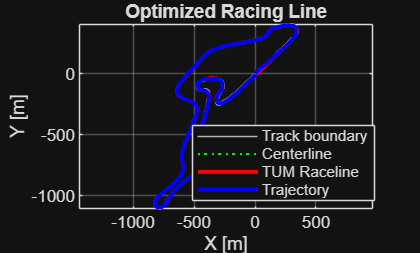

grayColor = [.7 .7 .7];
plot(x_left, y_left, 'Color', grayColor, 'LineWidth',0.5, 'DisplayName','Track boundary'); hold on;
plot(x_right, y_right,'Color', grayColor, 'LineWidth',0.5, 'HandleVisibility','off');
plot(x_center, y_center, 'g:', 'LineWidth', 1, 'DisplayName', 'Centerline');
plot(x_race_raw, y_race_raw, 'r-', 'LineWidth', 2, 'DisplayName', 'TUM Raceline');
plot(x_opt, y_opt, 'b-', 'LineWidth', 2, 'DisplayName', 'Trajectory');
xlabel('X [m]'); ylabel('Y [m]');
legend('Location', 'best');
title('Optimized Racing Line');
axis equal; grid on;

### Plot steering angle

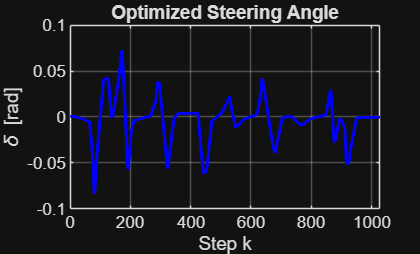

figure;
plot(delta_opt, 'b-', 'LineWidth', 1.5);
xlabel('Step k');
ylabel('\delta [rad]');
title('Optimized Steering Angle');
grid on;


fprintf('delta min = %.3f deg, max = %.3f deg\n', ...
        rad2deg(atan(delta_min)), rad2deg(atan(delta_max)));

delta min = -20.000 deg, max = 20.000 deg


fprintf('delta_opt min = %.3f deg, max = %.3f deg\n', ...
        rad2deg(atan(min(delta_opt))), rad2deg(atan(max(delta_opt))));

delta_opt min = -4.708 deg, max = 4.096 deg
